# Kitti DataSet localization model.

#### (Autonomous Vehicle Localization Using Onboard Sensors and HD-Geolocated Maps [MATLAB Project #20] - Spring 2024 Semester).

**Presented by: **

- Hazem Mohsen Abdelaziz 

- Yousra Adly Deifallah

#### Under Supervision of:

-  Prof. Dr. Mohamed Ibrahim Awad (Mechatronics Head Faculty of Engineering - Ain Shams University).

# Data Loading, Visualization, And Storing.

%Loading Dataset from extracted folder on our local machine
%Add dataset path below 
dataset_path = 'C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI\City_2011_09_26_drive_0009\2011_09_26\2011_09_26_drive_0009_sync';
%Start loading UNSYNC OXTS data to perform same for IMU based estimates
unSyncDataset_path = 'C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI\City_2011_09_26_drive_0009\2011_09_26\2011_09_26_drive_0009_extract';
%Go to images folder and check for how many images in there to represents
%number of frames
rgbFolderPath = strcat(dataset_path, '\image_02\data');
pngFiles = dir(fullfile(rgbFolderPath, '*.png'));
rgbVector = cell(1, numel(pngFiles));
%For Unsynced data
%Go to OXTS folder and check for how many Samples in there to represents
%number of frames
unsyncOxtsFolderPath = strcat(unSyncDataset_path, '\oxts\data');
unsyncOxtsFiles = dir(fullfile(unsyncOxtsFolderPath, '*.txt'));
%Setting number of frames and Sampling time according to certain dataset
framesNum = numel(pngFiles);
Ts = 0.1;
%And for Unsynced Data
unsyncFramesNum = numel(unsyncOxtsFiles);
unsyncIMUTs = 0.01;

%Store stereo camera first frame (For center cameras 0: Gray & 2: RGB)
gray_image = imread(fullfile(dataset_path, 'image_00\data', '0000000000.png'));
rgb_image = imread(fullfile(dataset_path, 'image_02\data', '0000000000.png'));

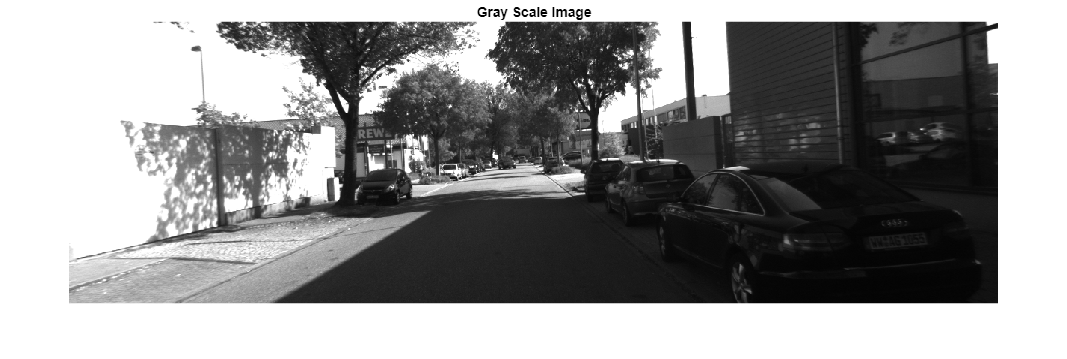

% Display the images
figure;
imshow(gray_image);

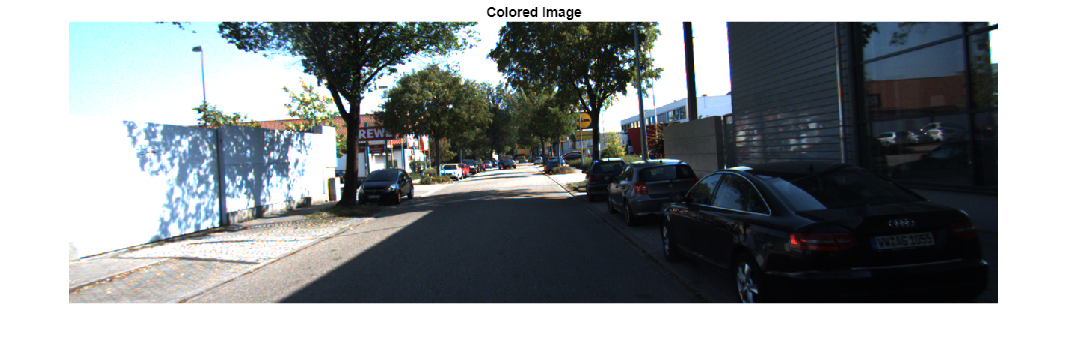

title('Gray Scale Image');
figure;
imshow(rgb_image);

title('Colored Image');

%Store Colored image in a image vector
for i = 1:numel(pngFiles)
    %Construct the full file path
    filePath = fullfile(rgbFolderPath, pngFiles(i).name);
    %Read the image and store it
    rgbVector{i} = imread(filePath);
end

%This Cell is to save a video consisting of multiple images in a vector
%Each image of type cell
%cd('') %Here you can enter the save location
%{
outputVideo = VideoWriter('output_video.avi'); 
outputVideo.FrameRate = 10; %Frame rate that the images vector recorded at for a better display
open(outputVideo);

for i = 1:numel(rgbVector)
    % Convert image from cell to matrix
    frame =rgbVector{i};
    
    %write the frame to the video
    writeVideo(outputVideo, frame);
end

% Close the video file
close(outputVideo);
%}

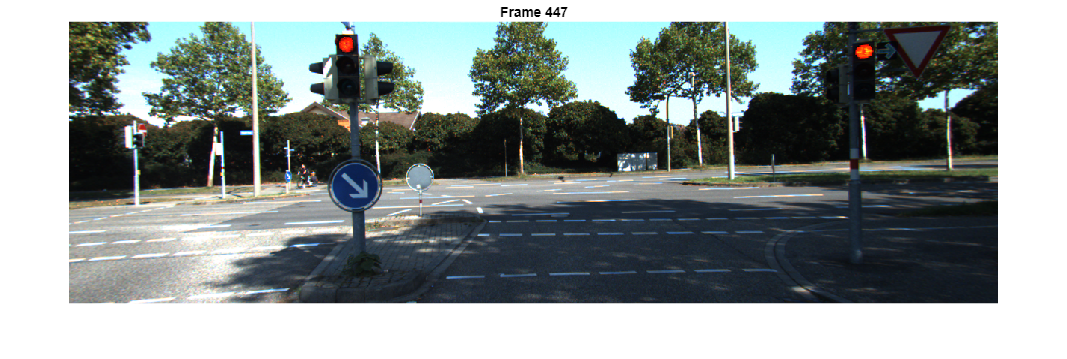

%This cell is to display the sequence of rgb colored image frames
for i = 1:numel(rgbVector)
    % Display the current image
    imshow(rgbVector{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 

end

pcdFolderPath = strcat(dataset_path, '\velodyne_points\data');
pcdFiles = dir(pcdFolderPath);
% || CAUTION || %
%This section is to convert from bin file data to 
% !! This section is to be run once to avoid overwriting and saving files
%multiple times, to convert it for the fisrt time uncomment the section
%bellow
%{
cd(pcdFolderPath);
for i = 1:length(pcdFiles)
    filename = pcdFiles(i).name;
    if(length(filename) > 10)
        binOpen = fopen(filename, 'rb'); %Open binary in read mode
        binData = fread(binOpen, [4, inf], 'single')'; %Reading data from binary file
        fclose(binOpen);
        extension_to_remove = '.bin';
        original_str = filename;
        start_idx = strfind(original_str, extension_to_remove);
        end_idx = start_idx + length(extension_to_remove) - 1;
        modified_str = original_str;
        modified_str(start_idx:end_idx) = ''; 
        save(strcat(modified_str,'.mat'), 'binData');
    end
end
%}

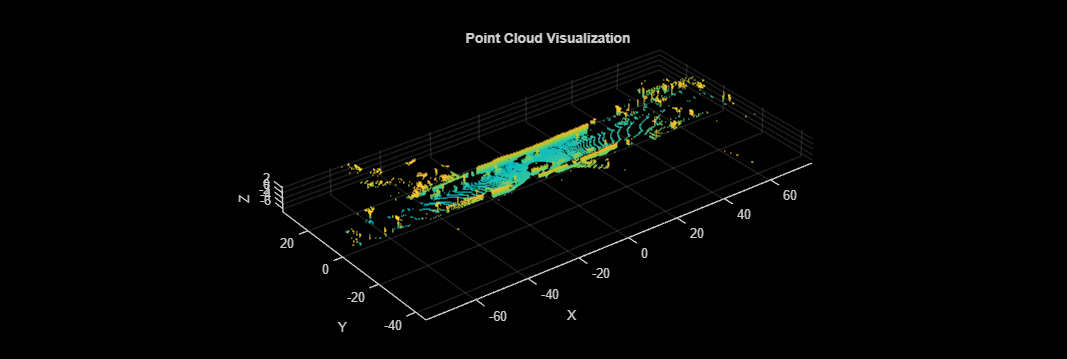

%visualize a LiDAR point cloud from a frame
point_cloud = load(fullfile(pcdFolderPath, '0000000000.mat'));
pcdX = point_cloud.binData(:,1);
pcdY = point_cloud.binData(:,2);
pcdZ = point_cloud.binData(:,3);
point_cloud_data = [pcdX, pcdY, pcdZ];
pcshow(point_cloud_data)
xlabel('X');
ylabel('Y');
zlabel('Z');

title('Point Cloud Visualization');

pcdMat = NaN(100000, 3, framesNum); %This matrix will hold our point cloud
matFiles = dir(fullfile(pcdFolderPath, '*.mat'));
for i = 1:numel(matFiles)
    point_cloud = load(fullfile(pcdFolderPath, matFiles(i).name));
    pcdMat(1:size(point_cloud.binData(:,1)),1,i) = point_cloud.binData(:,1);
    pcdMat(1:size(point_cloud.binData(:,2)),2,i) = point_cloud.binData(:,2);
    pcdMat(1:size(point_cloud.binData(:,3)),3,i) = point_cloud.binData(:,3);
end

%Creating point cloud vector to downsample and filter (Preprocessing)
pointCloudObjects = cell(framesNum);
for i = 1:framesNum
    % Convert the array to a pointCloud object
    pointCloudObjects{i} = pointCloud(pcdMat(:,:,i));
    pointCloudObjects{i} = pcdownsample(pointCloudObjects{i}, 'gridAverage', 0.5);
    %PCD With outliers removal
    pointCloudObjects{i} = pcdenoise(pointCloudObjects{i}, 'Threshold', 0.5);
end

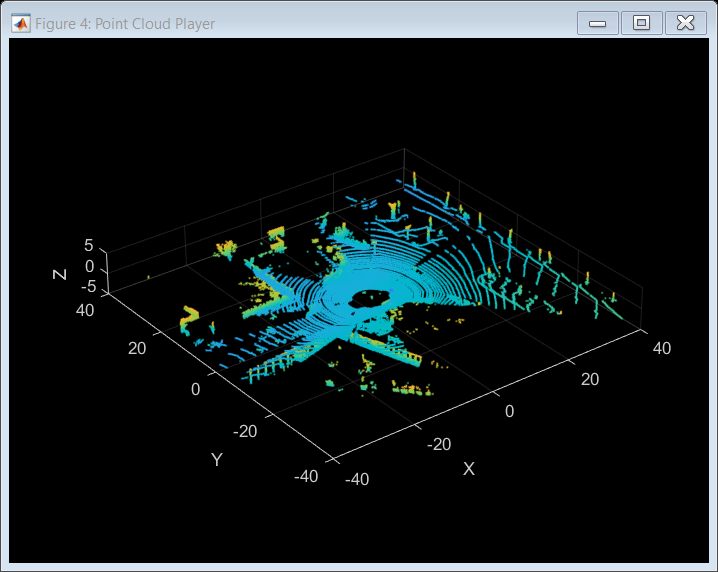

%To display 3D lidar data
xlimits = [-40 40];
ylimits = [-40 40];
zlimits = [ -5 5];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
for i = 1:numel(matFiles)
    pcdX = pcdMat(:,1,i);
    pcdY = pcdMat(:,2,i);
    pcdZ = pcdMat(:,3,i);
    point_cloud_data = [pcdX, pcdY, pcdZ];
    % Update the plot with the point cloud for the current frame
    view(player, point_cloud_data);
    %pause(0.01); % Adjust the pause duration as needed

end

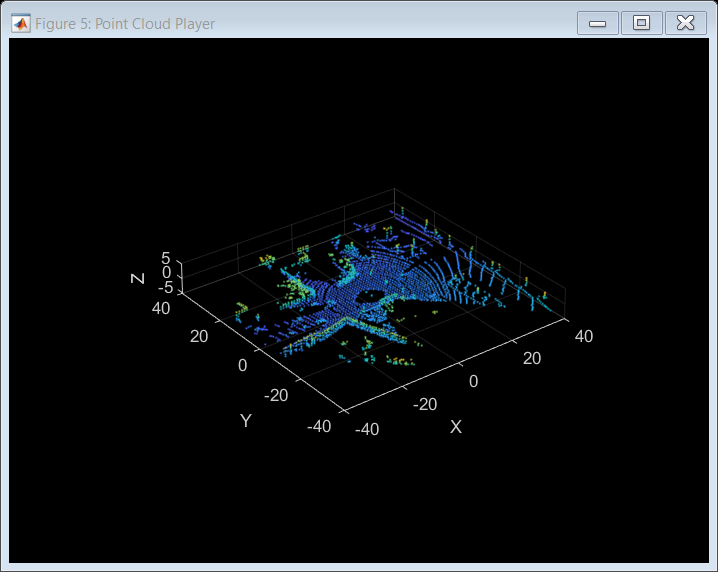

%To display 3D lidar data (Downsampled)
xlimits = [-40 40];
ylimits = [-40 40];
zlimits = [ -5 5];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
for i = 1:numel(matFiles)
    % Update the plot with the point cloud for the current frame
    view(player, pointCloudObjects{i});
    %pause(0.01); % Adjust the pause duration as needed

end

%Reading GPS/IMU data from OXTS folder
%Data are stored in the format show at dataformat.txt file
oxtsFolderPath = strcat(dataset_path, '\oxts\data');
oxtsFiles = dir(oxtsFolderPath);
cd(oxtsFolderPath);
OXTS = zeros(framesNum,30);
j = 1;
for i = 3:length(oxtsFiles) % 3 to avoid backward in location
    filename = oxtsFiles(i).name;
    if(length(filename) > 5)
        OXTS(j,:) = importdata(filename);
    end
    j = j +1;
end
%Go back to where the live script located to be used in further processing
%for GPS data (Where LLA_to_Local function script exists)
cd('C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI');

%Seperating OXTS folder to Data vectors needed for further processing
%To Get GPS-Based Position(Ground Truth Position)that will be converted to local frame:
latitude = OXTS(:,1);
longitude = OXTS(:,2);
altitude = OXTS(:,3);

%To Get (To evaluate integration model and difference):
roll = OXTS(:,4);
pitch = OXTS(:,5);
yaw = OXTS(:,6);

%To get velocity of vehcile (To evaluate integration model and difference):
vn = OXTS(:,7);
ve = OXTS(:,8);

%IMU Readings (To obtain Pose estimation based on IMU data only):
    %Accelerometer reading:
af = OXTS(:,15);
al = OXTS(:,16);
au = OXTS(:,17);
    %Groscope reading:
wf = OXTS(:,21);
wl = OXTS(:,22);
wu = OXTS(:,23);

%Creating time frame starting from Second 0 
timeVector = 0:0.1:(framesNum-1)*0.1;

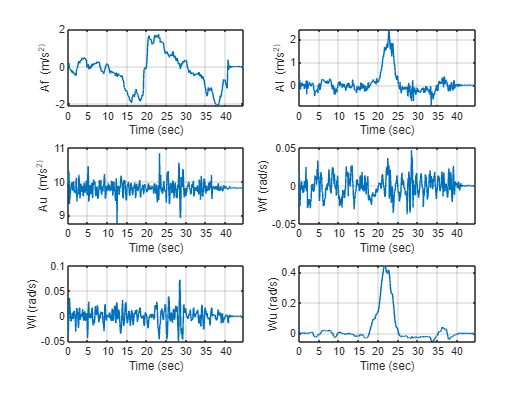

%Creating subplots to visualize IMU data
figure;

subplot(3,2,1);
plot(timeVector, af);
xlabel('Time (sec)');
ylabel('Af (m/s^2)');
xticks(0:5:50);
grid("on");

subplot(3,2,2);
plot(timeVector, al);
xlabel('Time (sec)');
ylabel('Al (m/s^2)');
xticks(0:5:50);
grid("on");

subplot(3,2,3);
plot(timeVector, au);
xlabel('Time (sec)');
ylabel('Au (m/s^2)');
xticks(0:5:50);
grid("on");
subplot(3,2,4);
plot(timeVector, wf);
xlabel('Time (sec)');
ylabel('Wf (rad/s)');
xticks(0:5:50);
grid("on");

subplot(3,2,5);
plot(timeVector, wl);
xlabel('Time (sec)');
ylabel('Wl (rad/s)');
xticks(0:5:50);
grid("on");

subplot(3,2,6);
plot(timeVector, wu);
xlabel('Time (sec)');
ylabel('Wu (rad/s)');
xticks(0:5:50);

grid("on");

%Filtering input data, if needed uncomment below section
%{
Fs = 10; %sampling frequency
%cutoff frequency
cutoff_frequency = 1; % Specify the cutoff frequency for filtering high-frequency noise

%low-pass filter
[b, a] = butter(4, cutoff_frequency / (Fs / 2), 'low'); %4th-order Butterworth filter

% Apply the low-pass filter to the data
af = filtfilt(b, a, af);
al = filtfilt(b, a, al);
wu = filtfilt(b, a, wu);
vn = filtfilt(b, a, vn);
ve = filtfilt(b, a, ve);
%}

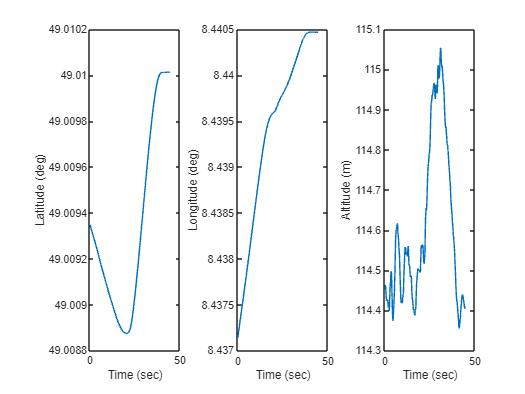

%Creating subplots to visualize GPS geodatic frame data
figure;
set(gcf, 'Color', 'white');

subplot(1,3,1);
plot(timeVector, latitude);
xlabel('Time (sec)');
ylabel('Latitude (deg)');

subplot(1,3,2);
plot(timeVector, longitude);
xlabel('Time (sec)');
ylabel('Longitude (deg)');

subplot(1,3,3);
plot(timeVector, altitude);
xlabel('Time (sec)');

ylabel('Altitude (m)');

# Loading Unsync Data.

%Reading GPS/IMU data from Unsynchronized OXTS folder
cd(unsyncOxtsFolderPath);
UNSYNCOXTS = zeros(framesNum,30);
j = 1;
for i = 1:length(unsyncOxtsFiles)
    filename = unsyncOxtsFiles(i).name;
    if(length(filename) > 5)
        UNSYNCOXTS(j,:) = importdata(filename);
    end
    j = j +1;
end
%Go back to where the live script located to be used in further processing
%for GPS data (Where LLA_to_Local function script exists)
cd('C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI');

%Seperating OXTS folder to Data vectors needed for further processing
%To Get GPS-Based Position(Ground Truth Position)that will be converted to local frame:
unsyncLatitude = UNSYNCOXTS(:,1);
unsyncLongitude = UNSYNCOXTS(:,2);
unsyncAltitude = UNSYNCOXTS(:,3);

%To Get (To evaluate integration model and difference):
unsyncRoll = UNSYNCOXTS(:,4);
unsynchPitch = UNSYNCOXTS(:,5);
unsyncYaw = UNSYNCOXTS(:,6);

%To get velocity of vehcile (To evaluate integration model and difference):
unsyncVn = UNSYNCOXTS(:,7);
unsyncVe = UNSYNCOXTS(:,8);

%IMU Readings (To obtain Pose estimation based on IMU data only):
    %Accelerometer reading:
unsyncAf = UNSYNCOXTS(:,15);
unsyncAl = UNSYNCOXTS(:,16);
unsyncAu = UNSYNCOXTS(:,17);
    %Groscope reading:
unsyncWf = UNSYNCOXTS(:,21);
unsyncWl = UNSYNCOXTS(:,22);
unsyncWu = UNSYNCOXTS(:,23);

%Creating time frame starting from Second 0 (Assuming Ts is const at 0.01s)
unsyncTimeVector = 0:0.01:(unsyncFramesNum-1)*0.01;

%Creating timeSeries from timestamps text file
uOxtsTsPath = strcat(unSyncDataset_path, '\oxts\', 'timestamps.txt');
fid = fopen(uOxtsTsPath, 'r');
timestamps_str = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
timestamps = datetime(timestamps_str{1}, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS', 'Format', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');
time_diff = diff(timestamps);
time_diff_seconds = seconds(time_diff);
uOxtsTs = zeros(1, unsyncFramesNum);
uOxtsTs(1) = 0.01;
uOxtsTs(2:end) = time_diff_seconds;
usOxtsTsRef = zeros(1, length(uOxtsTs)); %For a vector containing the time difference in second
for i = 2:length(uOxtsTs)
    usOxtsTsRef(i) = usOxtsTsRef(i-1) + uOxtsTs(i);
end

# GPS data conversion (Geodatic to local) and Visualization.

%Converting LLA cordinate frame position to Local frame position using GPS
%data obtained
GPSn = zeros(framesNum, 1);
GPSe = zeros(framesNum, 1);
unsyncGPSn = zeros(unsyncFramesNum, 1);
unsyncGPSe = zeros(unsyncFramesNum, 1);
%Refrencing motion to first frame readings
for i= 1:framesNum
    [deltaE, deltaN, ~] = lla_to_enu(latitude(1), longitude(1), altitude(1), latitude(i), longitude(i), altitude(i));
    GPSe(i) = deltaE;
    GPSn(i) = deltaN;
end
for i= 1:unsyncFramesNum
    [deltaE, deltaN, ~] = lla_to_enu(unsyncLatitude(1), unsyncLongitude(1), unsyncAltitude(1), unsyncLatitude(i), unsyncLongitude(i), unsyncAltitude(i));
    unsyncGPSe(i) = deltaE;
    unsyncGPSn(i) = deltaN;
end

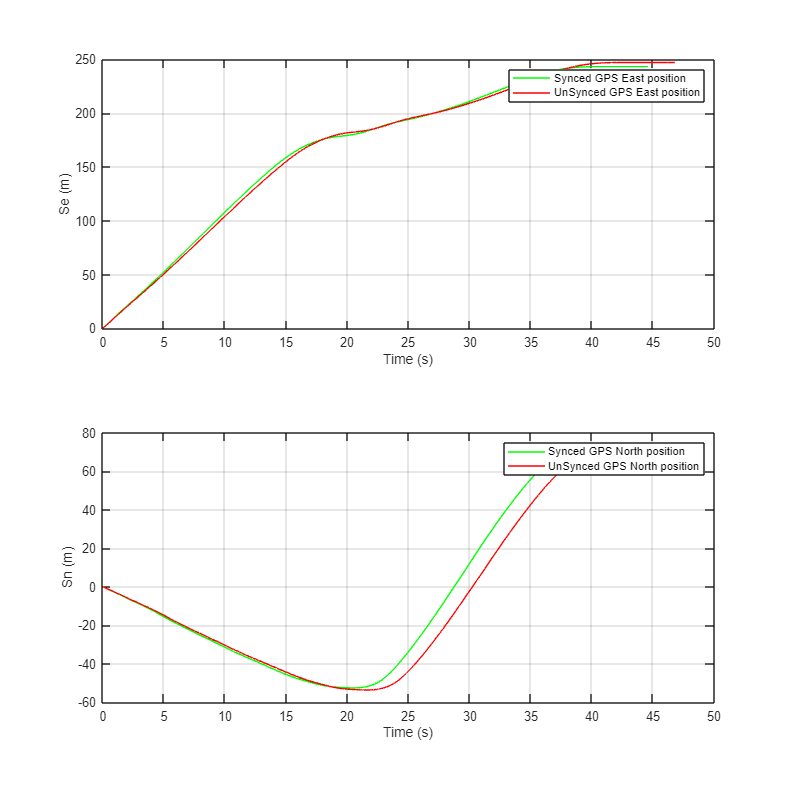

%Graph GPS based position
figure;
figure('Position', [50, 50, 1000, 1000]); % [left bottom width height]

subplot(2, 1, 1);
plot(timeVector, GPSe, 'g');
hold on;
plot(usOxtsTsRef, unsyncGPSe, 'r');
xlabel('Time (s)');
ylabel('Se (m)');
legend('Synced GPS East position', 'UnSynced GPS East position');
grid on;

subplot(2, 1, 2);
plot(timeVector, GPSn, 'g');
hold on;
plot(usOxtsTsRef, unsyncGPSn, 'r');
xlabel('Time (s)');
ylabel('Sn (m)');
legend('Synced GPS North position', 'UnSynced GPS North position');

grid on;

# IMU-Based Localization model, evaluation, and Stored data visualization.

%Convert Acceleration from sensor frame (Vehicle frame) to Global ENU Frame
Avehicle = [af,al];
Aenu = zeros(framesNum,2);
for i= 1:framesNum
    Aenu(i,1) = (cos(yaw(i)) * af(i)) -(sin(yaw(i)) * al(i));
    Aenu(i,2) = (sin(yaw(i)) * af(i)) +(cos(yaw(i)) * al(i));
end
Ae = Aenu(:,1);
An = Aenu(:,2);

%To get IMU-Based Pose: 
IMUYaw = zeros(framesNum, 1);
IMUn= zeros(framesNum,1);
IMUe= zeros(framesNum,1);
IMUVn = zeros(framesNum,1);
IMUVe = zeros(framesNum,1);

%Setting initial data
IMUYaw(1) = yaw(1);
IMUVn(1) = vn(1);
IMUVe(1) = ve(1);

%Assuming zero initial pose.
for i = 2:(framesNum)
    %Using double integration to get position from acceleration and single
    %step integration to get o
    % rientation from angular velocity
    IMUVn(i) = IMUVn(i-1) + (An(i) * Ts); %Velociy from integration (north direction)
    IMUVe(i) = IMUVe(i-1) + (Ae(i) * Ts); %Velociy from integration (east direction)

    IMUn(i) = IMUn(i-1) + (IMUVn(i) * Ts); %Position from integration (north direction)
    IMUe(i) = IMUe(i-1) + (IMUVe(i) * Ts); %Position from integration (east direction)

    IMUYaw(i) = IMUYaw(i-1) + (wu(i) * Ts); %orientation from integration (Yaw angle)
end    

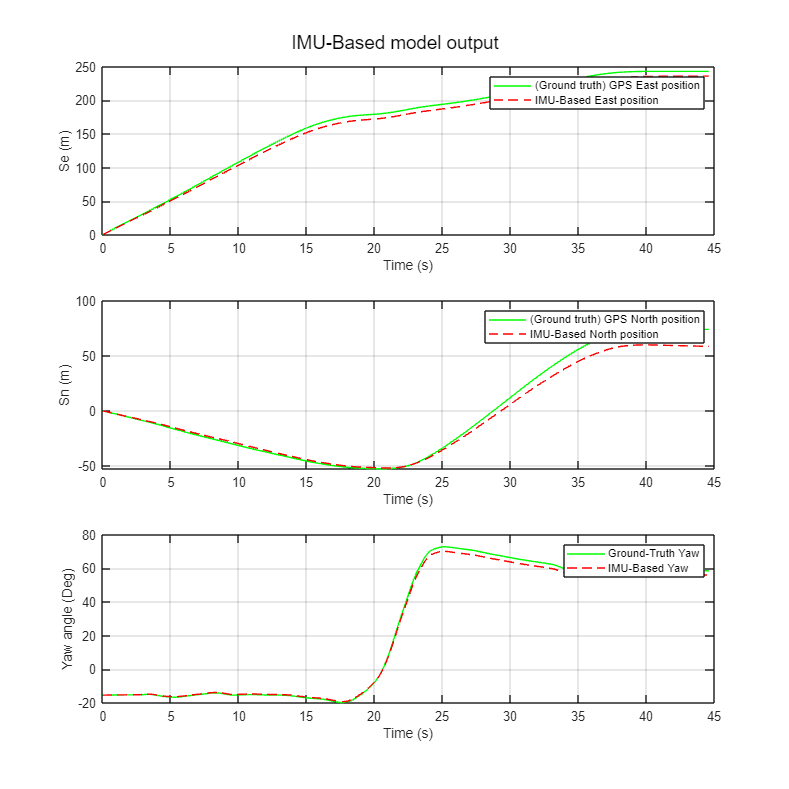

%Evaluating IMU-Based Position based on Ground truth data
figure;
figure('Position', [50, 50, 1000, 1000]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, GPSe, 'g');
hold on;
plot(timeVector, IMUe, 'r--');
xlabel('Time (s)');
ylabel('Se (m)');
legend('(Ground truth) GPS East position', 'IMU-Based East position');
grid on;

subplot(3, 1, 2);
plot(timeVector, GPSn, 'g');
hold on;
plot(timeVector, IMUn, 'r--');
xlabel('Time (s)');
ylabel('Sn (m)');
legend('(Ground truth) GPS North position', 'IMU-Based North position');
grid on;

subplot(3, 1, 3);
plot(timeVector, rad2deg(yaw), 'g');
hold on;
plot(timeVector, rad2deg(IMUYaw), 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (Deg)');
legend('Ground-Truth Yaw', 'IMU-Based Yaw');
grid on;

sgtitle('IMU-Based model output');

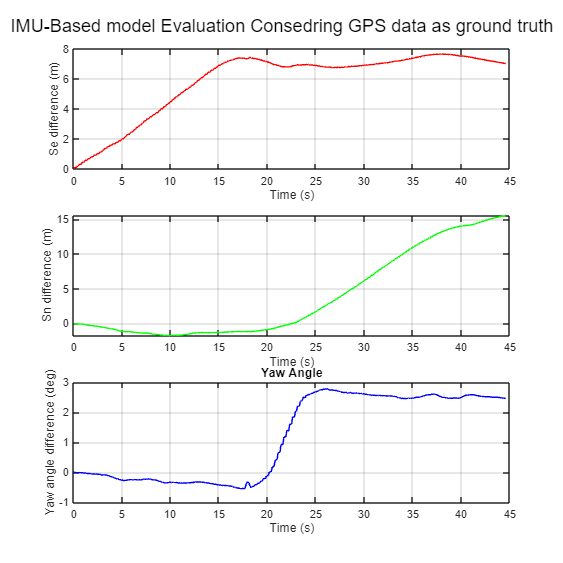

%Calculating Error (Difference between IMU and GPS data)
SeDiff = GPSe - IMUe;
SnDiff = GPSn- IMUn;
yawDiff = yaw- IMUYaw;

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, SeDiff, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, SnDiff, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, rad2deg(yawDiff), 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (deg)');
title('Yaw Angle')
grid on;


sgtitle('IMU-Based model Evaluation Consedring GPS data as ground truth');

# [Unsynchronized] IMU-Based Localization model, evaluation, and Stored data visualization.

%Convert Acceleration from sensor frame (Vehicle frame) to Global ENU Frame
unsyncAvehicle = [unsyncAf,unsyncAl];
unsyncAenu = zeros(unsyncFramesNum,2);
for i= 1:unsyncFramesNum
    unsyncAenu(i,1) = (cos(unsyncYaw(i)) * unsyncAf(i)) -(sin(unsyncYaw(i)) * unsyncAl(i));
    unsyncAenu(i,2) = (sin(unsyncYaw(i)) * unsyncAf(i)) +(cos(unsyncYaw(i)) * unsyncAl(i));
end
unsyncAe = unsyncAenu(:,1);
unsyncAn = unsyncAenu(:,2);

%To get Unsync IMU-Based Pose: 
unsyncIMUYaw = zeros(unsyncFramesNum, 1);
unsyncIMUn= zeros(unsyncFramesNum,1);
unsyncIMUe= zeros(unsyncFramesNum,1);
unsyncIMUVn = zeros(unsyncFramesNum,1);
unsyncIMUVe = zeros(unsyncFramesNum,1);

%Setting initial data
unsyncIMUYaw(1) = unsyncYaw(1);
unsyncIMUVn(1) = unsyncVn(1);
unsyncIMUVe(1) = unsyncVe(1);

%Assuming zero initial pose.
for i = 2:(unsyncFramesNum)
    %Using double integration to get position from acceleration and single
    %step integration to get o
    % rientation from angular velocity
    unsyncIMUVn(i) = unsyncIMUVn(i-1) + (unsyncAn(i) * unsyncIMUTs); %Velociy from integration (north direction)
    unsyncIMUVe(i) = unsyncIMUVe(i-1) + (unsyncAe(i) * unsyncIMUTs); %Velociy from integration (east direction)

    unsyncIMUn(i) = unsyncIMUn(i-1) + (unsyncIMUVn(i) * unsyncIMUTs); %Position from integration (north direction)
    unsyncIMUe(i) = unsyncIMUe(i-1) + (unsyncIMUVe(i) * unsyncIMUTs); %Position from integration (east direction)

    unsyncIMUYaw(i) = unsyncIMUYaw(i-1) + (unsyncWu(i) * unsyncIMUTs); %orientation from integration (Yaw angle)
end

%now using timestamps difference in time to evaluate
%Setting initial data
unsyncIMUYawT = zeros(unsyncFramesNum, 1);
unsyncIMUnT = zeros(unsyncFramesNum,1);
unsyncIMUeT = zeros(unsyncFramesNum,1);
unsyncIMUVnT = zeros(unsyncFramesNum,1);
unsyncIMUVeT = zeros(unsyncFramesNum,1);

unsyncIMUYawT(1) = unsyncYaw(1);
unsyncIMUVnT(1) = unsyncVn(1);
unsyncIMUVeT(1) = unsyncVe(1);

%Assuming zero initial pose.
for i = 2:(unsyncFramesNum)
    %Using double integration to get position from acceleration and single
    %step integration to get o
    % rientation from angular velocity
    unsyncIMUVnT(i) = unsyncIMUVnT(i-1) + (unsyncAn(i) * uOxtsTs(i)); %Velociy from integration (north direction)
    unsyncIMUVeT(i) = unsyncIMUVeT(i-1) + (unsyncAe(i) * uOxtsTs(i)); %Velociy from integration (east direction)

    unsyncIMUnT(i) = unsyncIMUnT(i-1) + (unsyncIMUVnT(i) * uOxtsTs(i)); %Position from integration (north direction)
    unsyncIMUeT(i) = unsyncIMUeT(i-1) + (unsyncIMUVeT(i) * uOxtsTs(i)); %Position from integration (east direction)

    unsyncIMUYawT(i) = unsyncIMUYawT(i-1) + (unsyncWu(i) * uOxtsTs(i)); %orientation from integration (Yaw angle)
end

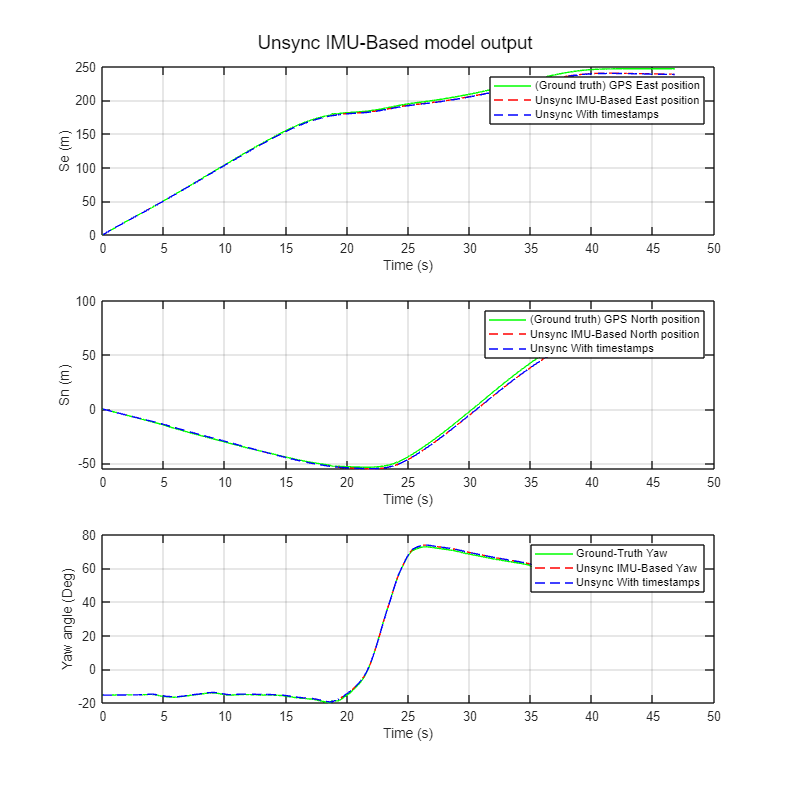

%Evaluating IMU-Based Position based on Ground truth data
figure;
figure('Position', [50, 50, 1000, 1000]); % [left bottom width height]

subplot(3, 1, 1);
plot(unsyncTimeVector, unsyncGPSe, 'g');
hold on;
plot(unsyncTimeVector, unsyncIMUe, 'r--');
hold on;
plot(usOxtsTsRef, unsyncIMUeT, 'b--');
xlabel('Time (s)');
ylabel('Se (m)');
legend('(Ground truth) GPS East position', 'Unsync IMU-Based East position', 'Unsync With timestamps');
grid on;

subplot(3, 1, 2);
plot(unsyncTimeVector, unsyncGPSn, 'g');
hold on;
plot(unsyncTimeVector, unsyncIMUn, 'r--');
hold on;
plot(usOxtsTsRef, unsyncIMUnT, 'b--');
xlabel('Time (s)');
ylabel('Sn (m)');
legend('(Ground truth) GPS North position', 'Unsync IMU-Based North position', 'Unsync With timestamps');
grid on;

subplot(3, 1, 3);
plot(unsyncTimeVector, rad2deg(unsyncYaw), 'g');
hold on;
plot(unsyncTimeVector, rad2deg(unsyncIMUYaw), 'r--');
hold on;
plot(usOxtsTsRef, rad2deg(unsyncIMUYawT), 'b--');
xlabel('Time (s)');
ylabel('Yaw angle (Deg)');
legend('Ground-Truth Yaw', 'Unsync IMU-Based Yaw', 'Unsync With timestamps');
grid on;

sgtitle('Unsync IMU-Based model output');

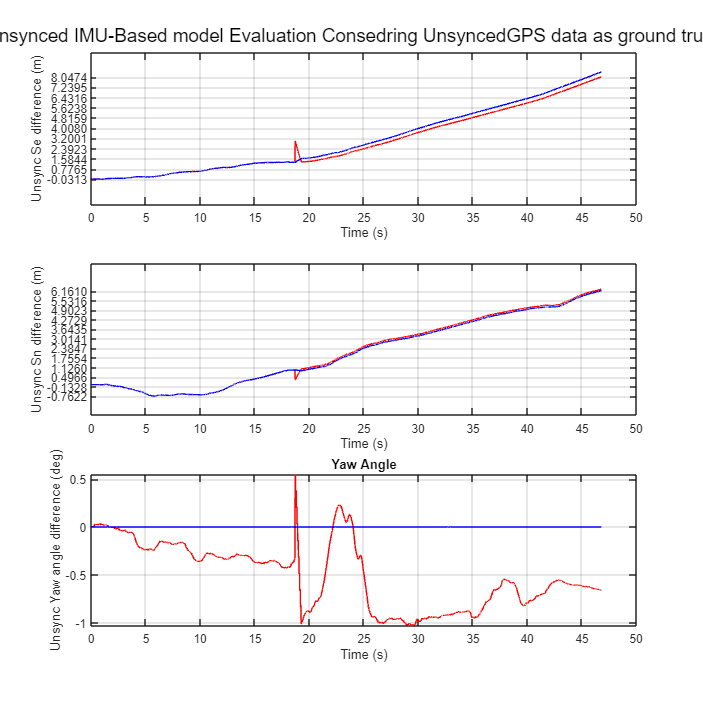

%Calculating Error (Difference between Unsync IMU and GPS data)
unsyncSeDiff = unsyncGPSe - unsyncIMUe;
unsyncSnDiff = unsyncGPSn - unsyncIMUn;
unsyncYawDiff = unsyncYaw - unsyncIMUYaw;
unsyncSeDiffT = unsyncGPSe - unsyncIMUeT;
unsyncSnDiffT = unsyncGPSn - unsyncIMUnT;
unsyncYawDiffT = unsyncYaw - unsyncIMUYawT;

%Graphing error
figure;
figure('Position', [50, 50, 750, 750]); % [left bottom width height]

subplot(3, 1, 1);
plot(unsyncTimeVector, unsyncSeDiff, 'r');
hold on;
plot(usOxtsTsRef, unsyncSeDiffT, 'b');
xlabel('Time (s)');
ylabel('Unsync Se difference (m)');
yticks(min(unsyncSeDiff):max(unsyncSeDiff)/10:max(unsyncSeDiff));
grid on;
subplot(3, 1, 2);
plot(unsyncTimeVector, unsyncSnDiff, 'r');
hold on;
plot(usOxtsTsRef, unsyncSnDiffT, 'b');
xlabel('Time (s)');
ylabel('Unsync Sn difference (m)');
yticks(min(unsyncSnDiff):max(unsyncSnDiff)/10:max(unsyncSnDiff));
grid on;
subplot(3, 1, 3);
plot(unsyncTimeVector, rad2deg(unsyncYawDiff), 'r');
hold on;
plot(usOxtsTsRef, deg2rad(unsyncYawDiffT), 'b');
xlabel('Time (s)');
ylabel('Unsync Yaw angle difference (deg)');
title('Yaw Angle')
grid on;


sgtitle('Unsynced IMU-Based model Evaluation Consedring UnsyncedGPS data as ground truth');

# Lidar-Based Localization model and evaluation.

lidarX = zeros(1, framesNum);
lidarY = zeros(1, framesNum);
lidarXBar = zeros(1, framesNum);
lidarYBar = zeros(1, framesNum);
lidarYaw = zeros(1, framesNum);
lidarYaw(1) = rad2deg(yaw(1)); %Setting initial starting angle
lidarSampleNumber = framesNum-1; 
for i = 1:lidarSampleNumber %for more accurate (full trajectory results we need to change from a limited number to total number of frames)
    % Check if each point cloud has at least three unique points
    ptCloudOne= pointCloudObjects{i};
    ptCloudTwo = pointCloudObjects{i+1};
    numptCloudOne = size(ptCloudOne.Location, 1);
    numptCloudTwo = size(ptCloudTwo.Location, 1);
    if numptCloudOne < 3 || numptCloudTwo < 3
        lidarX(i+1) = lidarX(i);
        lidarY(i+1) = lidarY(i);
        lidarXBar(i+1) = lidarXBar(i);
        lidarYBar(i+1) = lidarYBar(i);
        lidarYaw(i+1) = lidarYaw(i);
    else
        [tform, ~, ~] = pcregistericp(ptCloudTwo, ptCloudOne, Metric="planetToPlane");
        % Extract rotation matrix and translation vector from transformation matrix
        R = tform.T(1:3, 1:3);
        eulerAngles = -rotm2eul(R, 'XYZ');
        deltaYaw_vehicle_deg = double(rad2deg(eulerAngles(3)));
        t = tform.T(4, 1:3)';
        deltaX_vehicle_m =  (t(1) * sin(deg2rad(lidarYaw(i)))) - (t(2) * cos(deg2rad(lidarYaw(i)))); %for only lidar data
        deltaY_vehicle_m = - (t(2) * sin(deg2rad(lidarYaw(i)))) + (t(1) * cos(deg2rad(lidarYaw(i)))); %for only lidar data
        deltaX_vehicle_mBar =  (t(1) * sin(yaw(i))) - (t(2) * cos(yaw(i))); %for Lidar-INS referenced
        deltaY_vehicle_mBar = - (t(2) * sin(yaw(i))) + (t(1) * cos(yaw(i))); %for Lidar-INS referenced
        lidarX(i+1) = lidarX(i) + deltaX_vehicle_m;
        lidarY(i+1) = lidarY(i) + deltaY_vehicle_m;
        lidarXBar(i+1) = lidarXBar(i) + deltaX_vehicle_mBar;
        lidarYBar(i+1) = lidarYBar(i) + deltaY_vehicle_mBar;
        lidarYaw(i+1) = lidarYaw(i) + deltaYaw_vehicle_deg;
    end
    %Display number of iteration to see current progress
    str = sprintf('Processing iteration %d', i);
    disp(str);

Processing iteration 1
Processing iteration 2
Processing iteration 3
Processing iteration 4
Processing iteration 5
Processing iteration 6
Processing iteration 7
Processing iteration 8
Processing iteration 9
Processing iteration 10
Processing iteration 11
Processing iteration 12
Processing iteration 13
Processing iteration 14
Processing iteration 15
Processing iteration 16
Processing iteration 17
Processing iteration 18
Processing iteration 19
Processing iteration 20
Processing iteration 21
Processing iteration 22
Processing iteration 23
Processing iteration 24
Processing iteration 25
Processing iteration 26
Processing iteration 27
Processing iteration 28
Processing iteration 29
Processing iteration 30
Processing iteration 31
Processing iteration 32
Processing iteration 33
Processing iteration 34
Processing iteration 35
Processing iteration 36
Processing iteration 37
Processing iteration 38
Processing iteration 39
Processing iteration 40
Processing iteration 41
Processing iteration 42
P

end

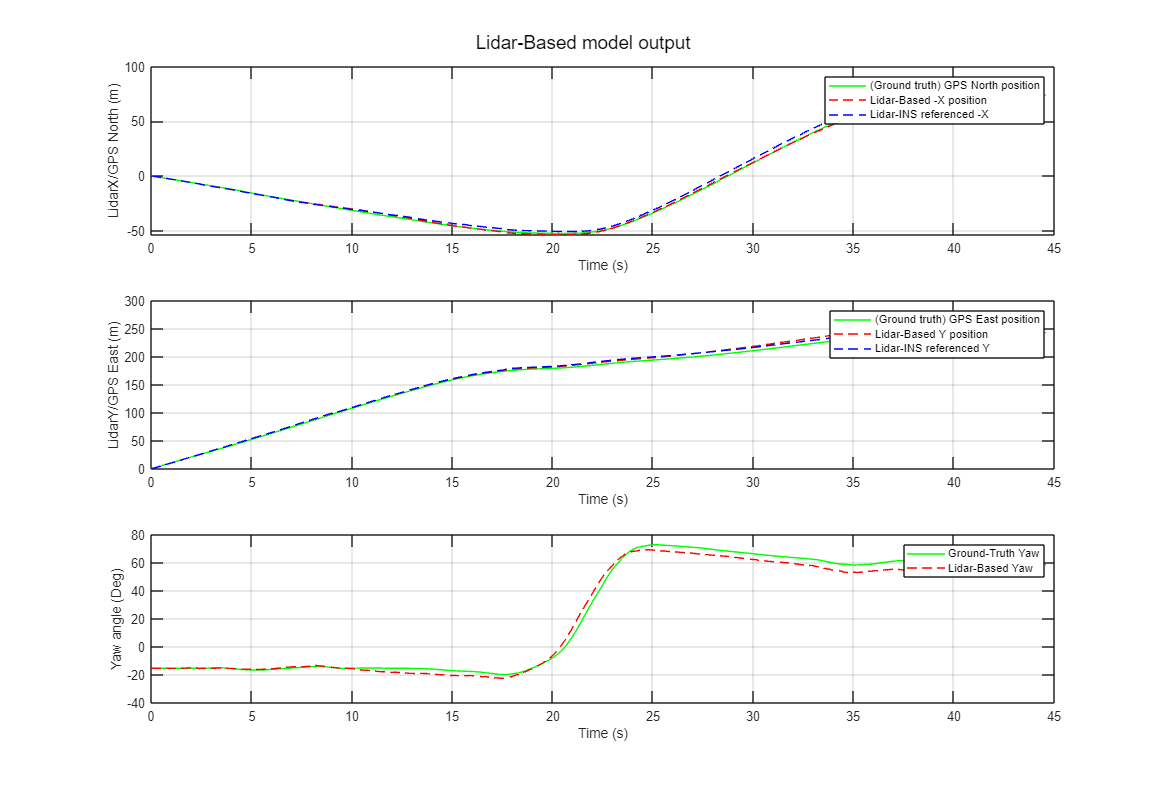

%Evaluating Lidar-Based Position based on Ground truth data
figure;
figure('Position', [50, 50, 1550, 1050]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector(1:(lidarSampleNumber+1)), GPSn(1:(lidarSampleNumber+1)), 'g');
hold on;
plot(timeVector(1:(lidarSampleNumber+1)), lidarX(1:(lidarSampleNumber+1)), 'r--'); % -ve to allign with enu frame aquired data (As referenced X axis in algorithm is opposite to north directions)
hold on;
plot(timeVector(1:(lidarSampleNumber+1)), lidarXBar(1:(lidarSampleNumber+1)), 'b--');
xlabel('Time (s)');
ylabel('LidarX/GPS North (m)');
legend('(Ground truth) GPS North position', 'Lidar-Based -X position', 'Lidar-INS referenced -X');
grid on;

subplot(3, 1, 2);
plot(timeVector(1:(lidarSampleNumber+1)), GPSe(1:(lidarSampleNumber+1)), 'g');
hold on;
plot(timeVector(1:(lidarSampleNumber+1)), lidarY(1:(lidarSampleNumber+1)), 'r--');
hold on;
plot(timeVector(1:(lidarSampleNumber+1)), lidarYBar(1:(lidarSampleNumber+1)), 'b--');
xlabel('Time (s)');
ylabel('LidarY/GPS East (m)');
legend('(Ground truth) GPS East position', 'Lidar-Based Y position', 'Lidar-INS referenced Y');
grid on;

subplot(3, 1, 3);
plot(timeVector(1:(lidarSampleNumber+1)), rad2deg(yaw(1:(lidarSampleNumber+1))), 'g');
hold on;
plot(timeVector(1:(lidarSampleNumber+1)), lidarYaw(1:(lidarSampleNumber+1)), 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (Deg)');
legend('Ground-Truth Yaw', 'Lidar-Based Yaw');
grid on;

sgtitle('Lidar-Based model output');

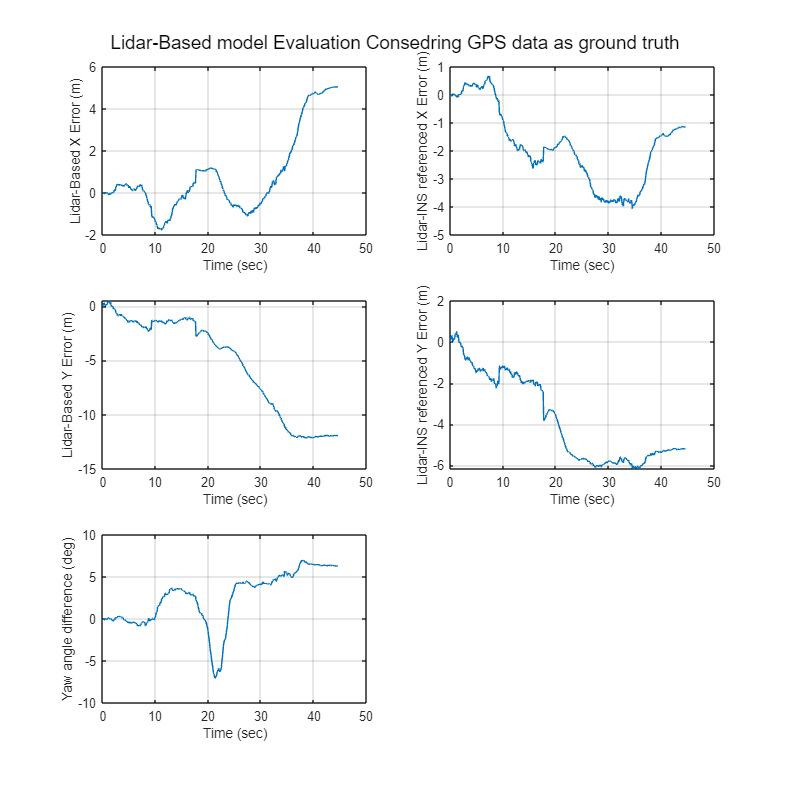

%Calculating Error (Difference between Lidar and GPS data)
LidarYDiff = GPSe - (lidarY)';
LidarXDiff = GPSn - (lidarX)';
LidarYBarDiff = GPSe - (lidarYBar)';
LidarXBarDiff = GPSn - (lidarXBar)';
LidaryawDiff = rad2deg(yaw) - (lidarYaw)';

%Graphing error
figure;
figure('Position', [50, 50, 1000, 1000]); % [left bottom width height]

subplot(3,2,1);
plot(timeVector(1:(lidarSampleNumber+1)), LidarXDiff(1:(lidarSampleNumber+1)));
xlabel('Time (sec)');
ylabel('Lidar-Based X Error (m)');
grid("on");

subplot(3,2,2);
plot(timeVector(1:(lidarSampleNumber+1)), LidarXBarDiff(1:(lidarSampleNumber+1)));
xlabel('Time (sec)');
ylabel('Lidar-INS referenced X Error (m)');
grid("on");

subplot(3,2,3);
plot(timeVector(1:(lidarSampleNumber+1)), LidarYDiff(1:(lidarSampleNumber+1)));
xlabel('Time (sec)');
ylabel('Lidar-Based Y Error (m)');
grid("on");

subplot(3,2,4);
plot(timeVector(1:(lidarSampleNumber+1)), LidarYBarDiff(1:(lidarSampleNumber+1)));
xlabel('Time (sec)');
ylabel('Lidar-INS referenced Y Error (m)');
grid("on");

subplot(3,2,5);
plot(timeVector(1:(lidarSampleNumber+1)),  LidaryawDiff(1:(lidarSampleNumber+1)));
xlabel('Time (sec)');
ylabel('Yaw angle difference (deg)');
grid("on");

sgtitle('Lidar-Based model Evaluation Consedring GPS data as ground truth');